clc;
load('rec_2m.mat') % input signal data to 'val' variable
ecgsig = val(1,1:5000);
N = length(ecgsig);
t=1:N;
tx=t./500;
fs=500;
tic;
nextPow2 = 2^nextpow2(N);
ecgsig1 = [ecgsig, zeros(1, nextPow2 - N)];
N = nextPow2;
p = log2(N);                            % Computing the number of conversion stages
Half = N/2;                             % Half the length of the array

for stage = 1:p                         % Stages of transformation
    for index = 0:(N/(2^(stage-1))):(N-1)    % Series of "butterflies" for each stage
        for n = 0:(Half-1)                   % Creating "butterfly" and saving the results
            pos = n + index + 1;                 % Index of the data sample
            pow = (2^(stage-1)) * n;              % Part of power of the complex multiplier
            w = exp((-1i)*(2*pi)*pow/N);          % Complex multiplier
            a = ecgsig1(pos) + ecgsig1(pos + Half);          % 1st part of the "butterfly" creating operation
            b = (ecgsig1(pos) - ecgsig1(pos + Half)) * w;    % 2nd part of the "butterfly" creating operation
            ecgsig1(pos) = a;                           % Saving computation of the 1st part
            ecgsig1(pos + Half) = b;                    % Saving computation of the 2nd part
        end
    end
    %disp(['Output at stage ', num2str(stage), ':']);
    %disp(ecgsig);
    Half = Half / 2;                            % Computing the next "Half" value
end

y = bitrevorder(ecgsig1);  % Bit-reverse the order of the output
elapsed_time = toc;
disp(['DIF-FFT Result (Time: ' num2str(elapsed_time) ' seconds):']);

DIF-FFT Result (Time: 0.081309 seconds):


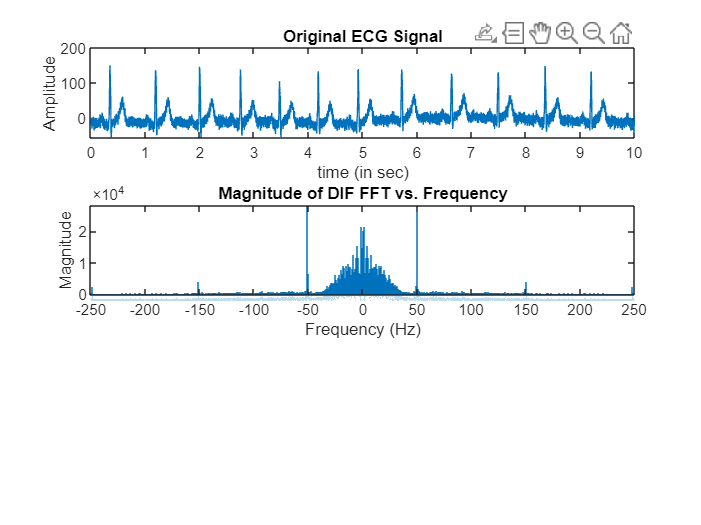

y=fftshift(y);
% Plot the original ECG signal 
figure;
subplot(3, 1, 1);
plot(tx, ecgsig);
title('Original ECG Signal');
xlabel('time (in sec)')
ylabel('Amplitude')
% Plot the magnitude of the DFT vs. frequency
subplot(3, 1, 2);
h=length(y);
l=(-h/2:(h/2-1))*(fs/h);
stem(l, abs(y),linewidth=0.005);
title('Magnitude of DIF FFT vs. Frequency');
xlabel('Frequency (Hz)');
ylabel('Magnitude');